# Sim plot handler

% *** Sim model handling ***
sim_num_samples = 700/0.02+1;
sim_index_del = 1:sim_num_samples;

real_num_samples = 699/0.02+1;
real_index_del = 1:real_num_samples;

step_sav = 10;
sim_index_del(1:step_sav:sim_num_samples) = [];
real_index_del(1:step_sav:real_num_samples) = [];

## Case 1 and 2 - Model - fl first tuning

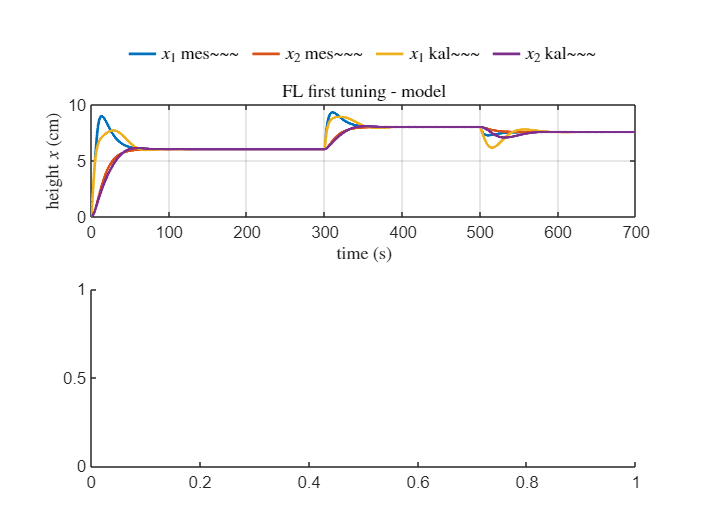

load("Results\Sim\sim_result_case_1_fl_u_first_tun.mat");
load("Results\Sim\sim_result_case_1_fl_x_first_tun.mat");
sim_result_case_1_fl_u_first_tun = delsample(sim_result_case_1_fl_u_first_tun,'Index',sim_index_del);
sim_result_case_1_fl_x_first_tun = delsample(sim_result_case_1_fl_x_first_tun,'Index',sim_index_del);
%
load("Results\Sim\sim_result_case_2_fl_u_first_tun.mat");
load("Results\Sim\sim_result_case_2_fl_x_first_tun.mat");
sim_result_case_2_fl_u_first_tun = delsample(sim_result_case_2_fl_u_first_tun,'Index',sim_index_del);
sim_result_case_2_fl_x_first_tun = delsample(sim_result_case_2_fl_x_first_tun,'Index',sim_index_del);


figure();
subplot(2,1,1);
    plot(sim_result_case_1_fl_x_first_tun);
    hold on;
    % set(gca,'ColorOrderIndex',1);
    plot(sim_result_case_2_fl_x_first_tun);
    xlim([0 700]);
    auto_plot('FL first tuning - model',...
            '$x_1$ mes|$x_2$ mes|$x_1$ kal|$x_2$ kal','time (s)|height $x$ (cm)');
subplot(2,1,2);

    plot(sim_result_case_1_fl_u_first_tun,'Color',porpora);

Unrecognized function or variable 'porpora'.

    hold on;
    plot(sim_result_case_2_fl_u_first_tun,'Color',light_blue);
    xlim([0 700]);
    auto_plot('',...
            '$u$ mes|$u$ kal','time (s)|voltage $u$ (V)');
saveas(gcf,'Plots/sim_result_fl_first_tun_fig.m');

## Case 1 and 2 - Model - fl second tuning

load("Results\Sim\sim_result_case_1_fl_u_second_tun.mat");
load("Results\Sim\sim_result_case_1_fl_x_second_tun.mat");
sim_result_case_1_fl_u_second_tun = delsample(sim_result_case_1_fl_u_second_tun,'Index',sim_index_del);
sim_result_case_1_fl_x_second_tun = delsample(sim_result_case_1_fl_x_second_tun,'Index',sim_index_del);
%
load("Results\Sim\sim_result_case_2_fl_u_second_tun.mat");
load("Results\Sim\sim_result_case_2_fl_x_second_tun.mat");
sim_result_case_2_fl_u_second_tun = delsample(sim_result_case_2_fl_u_second_tun,'Index',sim_index_del);
sim_result_case_2_fl_x_second_tun = delsample(sim_result_case_2_fl_x_second_tun,'Index',sim_index_del);


figure();
subplot(2,1,1);
    plot(sim_result_case_1_fl_x_second_tun);
    hold on;
    % set(gca,'ColorOrderIndex',1);
    plot(sim_result_case_2_fl_x_second_tun);
    xlim([0 700]);
    auto_plot('FL second tuning - model',...
            '$x_1$ mes|$x_2$ mes|$x_1$ kal|$x_2$ kal','time (s)|height $x$ (cm)');
subplot(2,1,2);
    plot(sim_result_case_1_fl_u_second_tun,'Color',porpora);
    hold on;
    plot(sim_result_case_2_fl_u_second_tun,'Color',light_blue);
    xlim([0 700]);
    auto_plot('',...
            '$u$ mes|$u$ kal','time (s)|voltage $u$ (V)');
saveas(gcf,'Plots/sim_result_fl_second_tun_fig.m');

## Case 1 and 2 - Real - fl first tuning

load("Results\Real\real_result_case_1_fl_u_first_tun.mat");
load("Results\Real\real_result_case_1_fl_x_first_tun.mat");
real_result_case_1_fl_u_first_tun = delsample(real_result_case_1_fl_u_first_tun,'Index',real_index_del);
real_result_case_1_fl_x_first_tun = delsample(real_result_case_1_fl_x_first_tun,'Index',real_index_del);
%
load("Results\Real\real_result_case_2_fl_u_first_tun.mat");
load("Results\Real\real_result_case_2_fl_x_first_tun.mat");
real_result_case_2_fl_u_first_tun = delsample(real_result_case_2_fl_u_first_tun,'Index',real_index_del);
real_result_case_2_fl_x_first_tun = delsample(real_result_case_2_fl_x_first_tun,'Index',real_index_del);


figure();
subplot(2,1,1);
    plot(real_result_case_1_fl_x_first_tun,'LineWidth',lw);
    hold on;
    % set(gca,'ColorOrderIndex',1);
    plot(real_result_case_2_fl_x_first_tun,'LineWidth',lw);
    xlim([0 700]);
    auto_plot('FL first tuning - real system',...
            '$x_1$ mes|$x_2$ mes|$x_1$ kal|$x_2$ kal','time (s)|height $x$ (cm)');
subplot(2,1,2);
    plot(real_result_case_1_fl_u_first_tun,'Color',porpora);
    hold on;
    plot(real_result_case_2_fl_u_first_tun,'Color',light_blue);
    xlim([0 700]);
    auto_plot('',...
            '$u$ mes|$u$ kal','time (s)|voltage $u$ (V)');
saveas(gcf,'Plots/real_result_fl_first_tun_fig.m');

## Case 1 and 2 - Real - fl second tuning

load("Results\Real\real_result_case_1_fl_u_second_tun.mat");
load("Results\Real\real_result_case_1_fl_x_second_tun.mat");
real_result_case_1_fl_u_second_tun = delsample(real_result_case_1_fl_u_second_tun,'Index',real_index_del);
real_result_case_1_fl_x_second_tun = delsample(real_result_case_1_fl_x_second_tun,'Index',real_index_del);
%
load("Results\Real\real_result_case_2_fl_u_second_tun.mat");
load("Results\Real\real_result_case_2_fl_x_second_tun.mat");
real_result_case_2_fl_u_second_tun = delsample(real_result_case_2_fl_u_second_tun,'Index',real_index_del);
real_result_case_2_fl_x_second_tun = delsample(real_result_case_2_fl_x_second_tun,'Index',real_index_del);


figure();
subplot(2,1,1);
    plot(real_result_case_1_fl_x_second_tun,'LineWidth',lw);
    hold on;
    % set(gca,'ColorOrderIndex',1);
    plot(real_result_case_2_fl_x_second_tun,'LineWidth',lw);
    xlim([0 700]);
    auto_plot('FL second tuning - real system',...
            '$x_1$ mes|$x_2$ mes|$x_1$ kal|$x_2$ kal','time (s)|height $x$ (cm)');
subplot(2,1,2);
    plot(real_result_case_1_fl_u_second_tun,'Color',porpora);
    hold on;
    plot(real_result_case_2_fl_u_second_tun,'Color',light_blue);
    xlim([0 700]);
    auto_plot('',...
            '$u$ mes|$u$ kal','time (s)|voltage $u$ (V)');
saveas(gcf,'Plots/real_result_fl_second_tun_fig.m');

## Case 1 and 2 - Model - sc

load("Results\Sim\sim_result_case_1_sc_u.mat");
load("Results\Sim\sim_result_case_1_sc_x.mat");
sim_result_case_1_sc_u = delsample(sim_result_case_1_sc_u,'Index',sim_index_del);
sim_result_case_1_sc_x = delsample(sim_result_case_1_sc_x,'Index',sim_index_del);
%
load("Results\Sim\sim_result_case_2_sc_u.mat");
load("Results\Sim\sim_result_case_2_sc_x.mat");
sim_result_case_2_sc_u = delsample(sim_result_case_2_sc_u,'Index',sim_index_del);
sim_result_case_2_sc_x = delsample(sim_result_case_2_sc_x,'Index',sim_index_del);


figure();
subplot(2,1,1);
    plot(sim_result_case_1_sc_x,'LineWidth',lw);
    hold on;
    % set(gca,'ColorOrderIndex',1);
    plot(sim_result_case_2_sc_x,'LineWidth',lw);
    xlim([0 700]);
    auto_plot('SC - model',...
            '$x_1$ mes|$x_2$ mes|$x_1$ kal|$x_2$ kal','time (s)|height $x$ (cm)');
subplot(2,1,2);
    plot(sim_result_case_1_sc_u,'Color',porpora);
    hold on;
    plot(sim_result_case_2_sc_u,'Color',light_blue);
    xlim([0 700]);
    auto_plot('',...
            '$u$ mes|$u$ kal','time (s)|voltage $u$ (V)');
saveas(gcf,'Plots/sim_result_sc_fig.m');

## Case 1 and 2 - Real - sc

load("Results\Real\real_result_case_1_sc_u.mat");
load("Results\Real\real_result_case_1_sc_x.mat");
real_result_case_1_sc_u = delsample(real_result_case_1_sc_u,'Index',real_index_del);
real_result_case_1_sc_x = delsample(real_result_case_1_sc_x,'Index',real_index_del);
%
load("Results\Real\real_result_case_2_sc_u.mat");
load("Results\Real\real_result_case_2_sc_x.mat");
real_result_case_2_sc_u = delsample(real_result_case_2_sc_u,'Index',real_index_del);
real_result_case_2_sc_x = delsample(real_result_case_2_sc_x,'Index',real_index_del);


figure();
subplot(2,1,1);
    plot(real_result_case_1_sc_x,'LineWidth',lw);
    hold on;
    % set(gca,'ColorOrderIndex',1);
    plot(real_result_case_2_sc_x,'LineWidth',lw);
    xlim([0 700]);
    auto_plot('SC - real system',...
            '$x_1$ mes|$x_2$ mes|$x_1$ kal|$x_2$ kal','time (s)|height $x$ (cm)');
subplot(2,1,2);
    plot(real_result_case_1_sc_u,'Color',porpora);
    hold on;
    plot(real_result_case_2_sc_u,'Color',light_blue);
    xlim([0 700]);
    auto_plot('',...
            '$u$ mes|$u$ kal','time (s)|voltage $u$ (V)');
saveas(gcf,'Plots/real_result_sc_fig.m');